elementos_nome_ficheiro = "projetoMComp_elementos_T6.txt";
nos_nome_ficheiro = "projetoMComp_nos_T6.txt";

[x, y, tri6] = Gerar_Malha(elementos_nome_ficheiro, nos_nome_ficheiro);

[Kg, fg] = Assem_TRI6(x, y, tri6)

Kg =    -4.7765         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -3.4835         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.1324         0         0         0   -0.1549         0         0   -0.1608   -0.1626   -0.2267         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

fg =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



nos = selecionar_nos(x, -1900)

nos =    388
   389
   390
   391
   392
   393
   394
   395
   396
   397


elementos = selecionar_elementos(tri6, nos)

elementos =    142   145   146   150   151   153



tri6(elementos,:)

ans =      1   389   390   279   393   280
   430   502   388   442   394   283
    55   388   389   285   395   282
     1   390   391   280   396   289
   445   392   503   292   397   466
   392    58   391   294   290   398


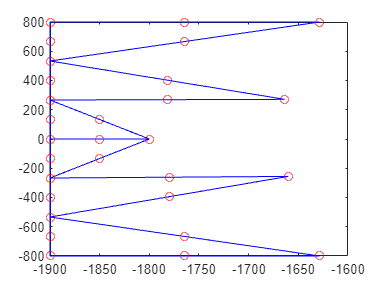


visualisar_malha_simples(x, y, tri6(elementos,:))


fg = neumann(tri6, elementos, nos, fg, 2500)

fg =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
